l1=45;l2=105;l3=105;l4=100;

a1=0;a2=l2;a3=l3;a4=l4;
alpha1=-pi/2;alpha2=0;alpha3=0;alpha4=0;
d1=l1;d2=0;d3=0;d4=0;
offset1=0;offset2=-pi/2;offset3=0;offset4=0;

J1=Revolute('a',a1, 'alpha',alpha1, 'd',d1, 'offset',offset1);
J2=Revolute('a',a2, 'alpha',alpha2, 'd',d2, 'offset',offset2);
J3=Revolute('a',a3, 'alpha',alpha3, 'd',d3, 'offset',offset3);
J4=Revolute('a',a4, 'alpha',alpha4, 'd',d4, 'offset',offset4);

T=[ 0 0 1 0;
    1 0 0 0;
    0 1 0 0;
    0 0 0 1];
ws = [-150,150,-150,150,-50,500];
robot = SerialLink([J1 J2 J3 J4], 'tool',T)

 
robot = 
 
noname:: 4 axis, RRRR, stdDH, fastRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         45|          0|    -1.5708|          0|
|  2|         q2|          0|        105|          0|    -1.5708|
|  3|         q3|          0|        105|          0|          0|
|  4|         q4|          0|        100|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0), RPY/xyz = (0, 90, 90) deg                
 


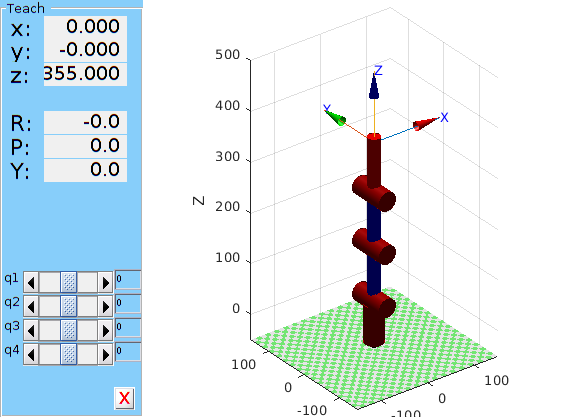

robot.teach([0 0 0 0], 'workspace', ws, 'noname');

MTH1=robot.fkine([0 0 0 0])

 

MTH1 = 
         1         0         0         0
         0         1         0         0
         0         0         1       355
         0         0         0         1


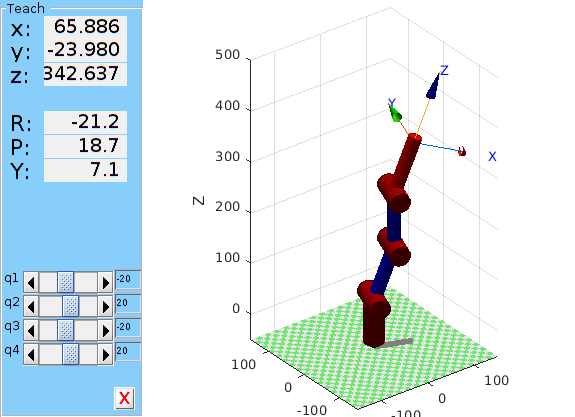

robot.teach([-20 20 -20 20]*pi/180, 'workspace', ws, 'noname');

MTH2=robot.fkine([-20 20 -20 20]*pi/180)

 

MTH2 = 
    0.8830    0.3420    0.3214     65.89
   -0.3214    0.9397   -0.1170    -23.98
   -0.3420         0    0.9397     342.6
         0         0         0         1


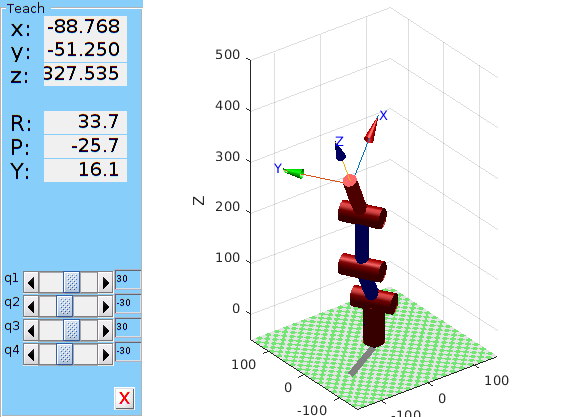

robot.teach([30 -30 30 -30]*pi/180, 'workspace', ws, 'noname');

MTH3=robot.fkine([30 -30 30 -30]*pi/180)

 

MTH3 = 
    0.7500   -0.5000   -0.4330    -88.77
    0.4330    0.8660   -0.2500    -51.25
    0.5000         0    0.8660     327.5
         0         0         0         1


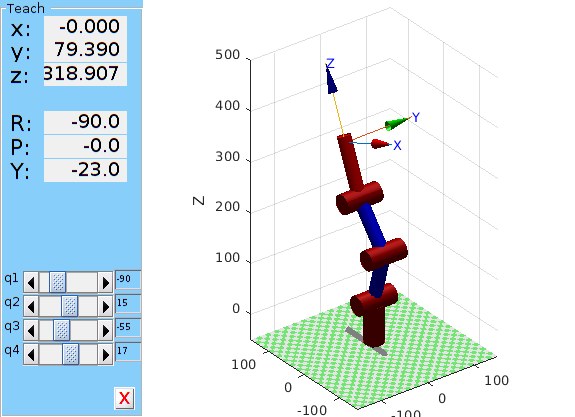

robot.teach([-90 15 -55 17]*pi/180, 'workspace', ws, 'noname');

MTH4=robot.fkine([-90 15 -55 17]*pi/180)

 

MTH4 = 
         0         1         0         0
   -0.9205         0    0.3907     79.39
    0.3907         0    0.9205     318.9
         0         0         0         1


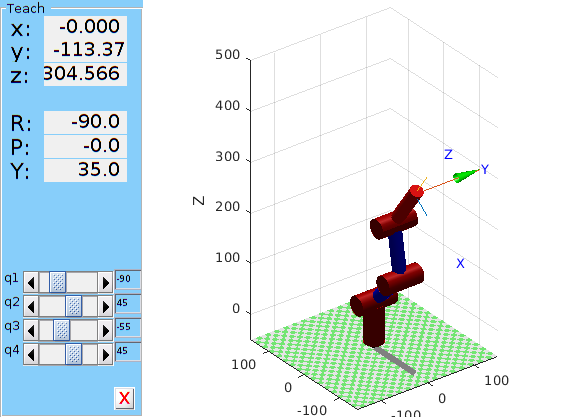

robot.teach([-90 45 -55, 45]*pi/180, 'workspace', ws, 'noname');

MTH5=robot.fkine([-90 45 -55 17]*pi/180)

 

MTH5 = 
         0         1         0         0
   -0.9925         0   -0.1219     -68.2
   -0.1219         0    0.9925     321.9
         0         0         0         1
